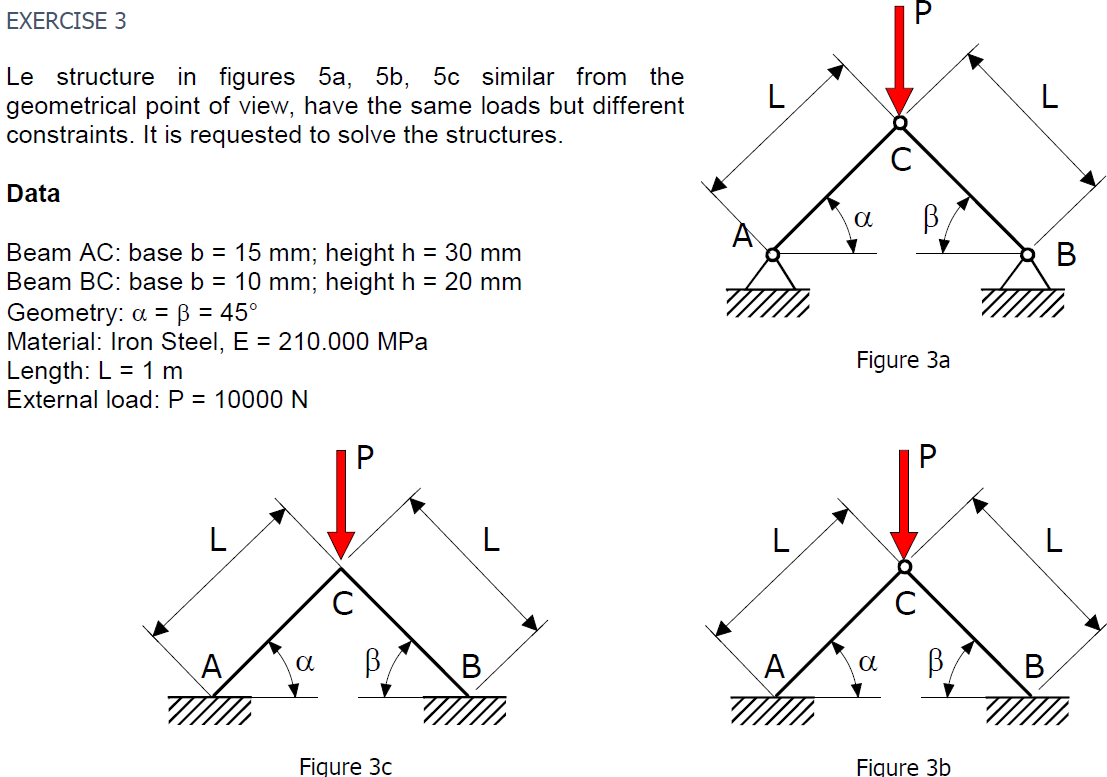

syms b h I E l P k Fs Ma Fa yb K phi2

b=[15 10]'

b =     15
    10


h=[10 20]'

h =     10
    20



I1=b(1)*h(1)^3/12*10^-12

I1 = 1.2500e-09

I2=b(2)*h(2)^3/12*10^-12

I2 = 6.6667e-09


E=210*10^9

E = 2.1000e+11

l1=1

l1 = 1

l2=l1;
alfa=rad2deg(45)

alfa = 2.5783e+03

beta=rad2deg(180-45)

beta = 2.5783e+03


R1=[cos(alfa) -sin(alfa);sin(alfa) cos(alfa)]

R1 =    -0.5918   -0.8061
    0.8061   -0.5918


R2=[cos(beta) -sin(beta);sin(beta) cos(beta)]

R2 =    -0.5918   -0.8061
    0.8061   -0.5918





K1 =(E*I1/l1^3)*[     12 6*l1 -12 6*l1;
                 6*l1 4*l1^2 6*l1 2*l1^2;
                -12 -6*l1 12 -6*l1;
                6*l1 2*l1^2 -6*l1 4*l1^2;];
% K1(:,1:3)=0;
K1=R1'*K1*R1

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.


K2 =(E*I2/l2^3)*[     12 6*l2 -12 6*l2;
                 6*l2 4*l2^2 6*l2 2*l2^2;
                -12 -6*l2 12 -6*l2;
                6*l2 2*l2^2 -6*l2 4*l2^2;];
K2=R2'*K2*R2

% K2(:,1)=0;
% K2(:,3:3)=0;
K2

